# Invariant Transformation of Krajník

## What is it?

The Krajník invariant transform is a method for obtaining images invariant to illumination changes. It is based on the use of intrinsic images, which separate intrinsic surface properties (reflectance) from extrinsic properties (illumination). This approach makes it possible to reduce the influence of shadows and illumination variations on the image.

## Basic operation of the transformation

**1. RGB Spectral Model:**

The spectral response of a specific channel $\rho_k$ (with 𝑘 = {𝑟,𝑔,𝑏} ) is defined as: 


$$\rho_k = \sigma \int E(\lambda) S(\lambda) Q_k(\lambda) d\lambda$$


where:

- $\sigma$: constant factor denoting Lambert shading.

- $E(\lambda)$: incident illumination on the perceived surface element.

- $S(\lambda)$: spectral reflectance of the surface.

- $Q(\lambda)$: $k$ channel spectral sensitivity.

- $\lambda$: wavelength.

**2. Logarithmic transformation:**

The model is transformed to a logarithmic space to make it invariant to illumination. This is done by calculating the logarithm of the spectral response relative to a reference channel (e.g., blue):


$$\chi_{k,g} = \log \frac{\rho_{r,g}}{\rho_{b}}
$$


**3. Projection to an Invariant Space:**

The logarithmic-chromatic space is projected in a $\theta$ direction to obtain the invariant image.


$$I_{\theta} = \chi_{r} \cos \theta + \chi_{g} \sin \theta
$$


**4. Entropy Minimization:**

The $\theta$ angle that minimizes the entropy of the projected image is determined so that it is as invariant as possible to the illumination.


$$E_{\theta} = -\sum_{i} H_{\theta}(i) \log H_{\theta}(i)$$


where:

- $H_{\theta}(i)$: histogram projected in a $\theta$ direction.

## Implementation Analysis

**1. Input Parameters:**

- $RGB$: image in RGB format.

- $\theta$: projection angle.

**2. Separation of Channels:**

First, the function saves each image channel $R$, $G$, and $B$ separately.

R = double(RGB(:,:,1));
G = double(RGB(:,:,2));
B = double(RGB(:,:,3));

**3. Then calculate **$x_r$** and **$x_g$**.**

logR = log(R + 1); % I add 1 to avoid log(0)
logG = log(G + 1);
logB = log(B + 1);

psi1 = logR - logG;
psi2 = logG - logB;

**4. Calculation of the **$\theta$** parameter**

The parameter $\theta$ is canned in a separate function and passed as a parameter.

angles = linspace(0, pi, 180);
min_entropy = Inf;
theta = 0;

for angle = angles
    I_proj = x_r * cos(angle) + x_g * sin(angle);
    counts = histcounts(I_proj(:), 256, 'Normalization', 'probability');
    entropy_val = -sum(counts .* log(counts + eps));

    if entropy_val < min_entropy
        min_entropy = entropy_val;
        theta = angle;
    end
end

**5. Invariant Transformation:**

Finally, the function performs the invariant transformation with the angle $\theta$:

I_Krajnik = x_r * cos(theta) + x_g * sin(theta);

## Complete code

function theta = calcular_theta_krajnik(imagen)
    % Separate RGB channels and calculate the logarithmic chromaticity
    logR = log(double(imagen(:,:,1)) + 1);
    logG = log(double(imagen(:,:,2)) + 1);
    logB = log(double(imagen(:,:,3)) + 1);

    % Color components
    x_r = logR - logG;
    x_g = logG - logB;

    % Define range of angles and minimum entropy initial value
    angles = linspace(0, pi, 180);
    min_entropy = Inf;
    theta = 0;

    % Finding the angle that minimizes entropy
    for angle = angles
        I_proj = x_r * cos(angle) + x_g * sin(angle);
        counts = histcounts(I_proj(:), 256, 'Normalization', 'probability');
        entropy_val = -sum(counts .* log(counts + eps));

        if entropy_val < min_entropy
            min_entropy = entropy_val;
            theta = angle;
        end
    end
end

function I_Krajnik = krajnik_transform(RGB, theta)
    % RGB image separation by channels in double
    R = double(RGB(:,:,1));
    G = double(RGB(:,:,2));
    B = double(RGB(:,:,3));
    
    % Calculation of the logarithmic chromaticity plus 1 to avoid log(0)
    logR = log(R + 1);
    logG = log(G + 1);
    logB = log(B + 1);
    
    % Calculation of x_r and x_g
    x_r = logR - logG;
    x_g = logG - logB;
    
    % Invariant transformation
    I_Krajnik = x_r * cos(theta) + x_g * sin(theta);
end

An example of a program image and its corresponding transformation:

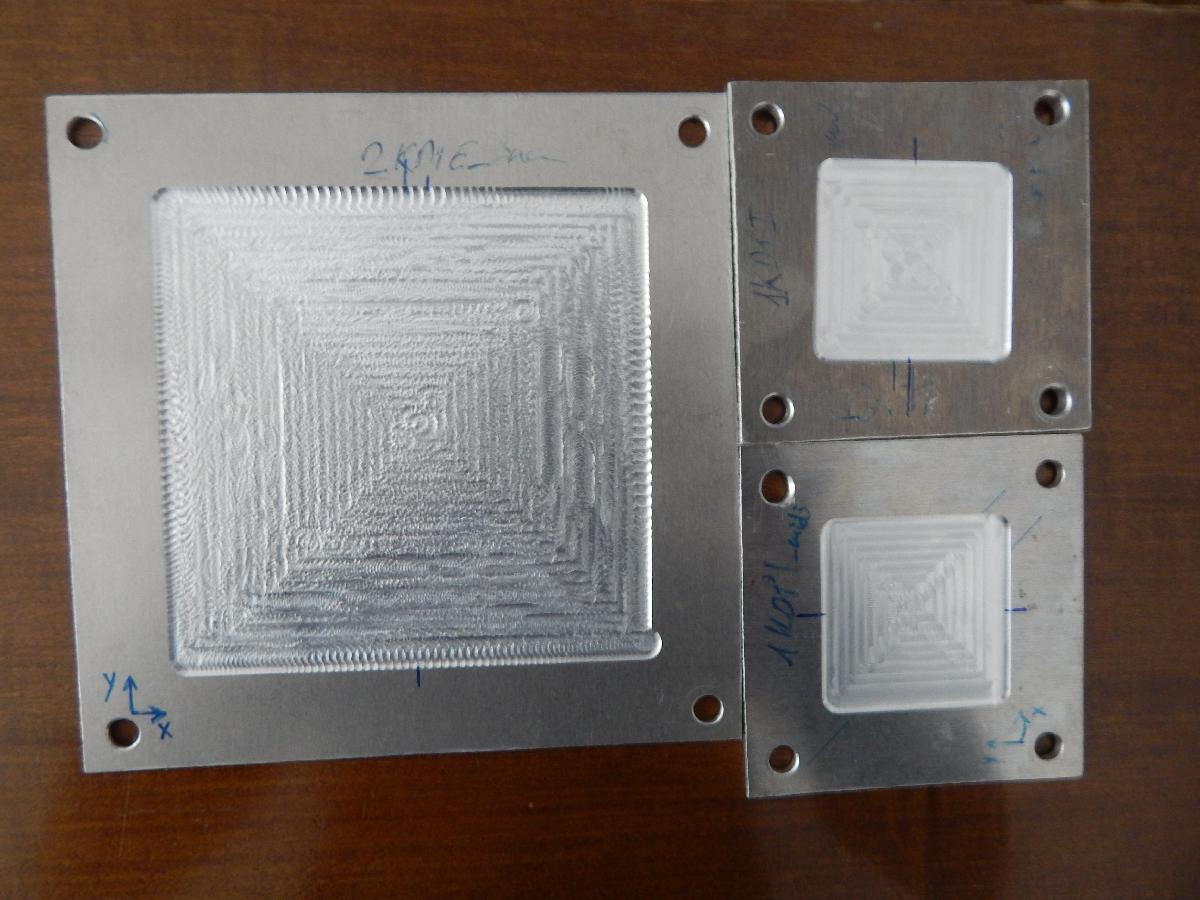    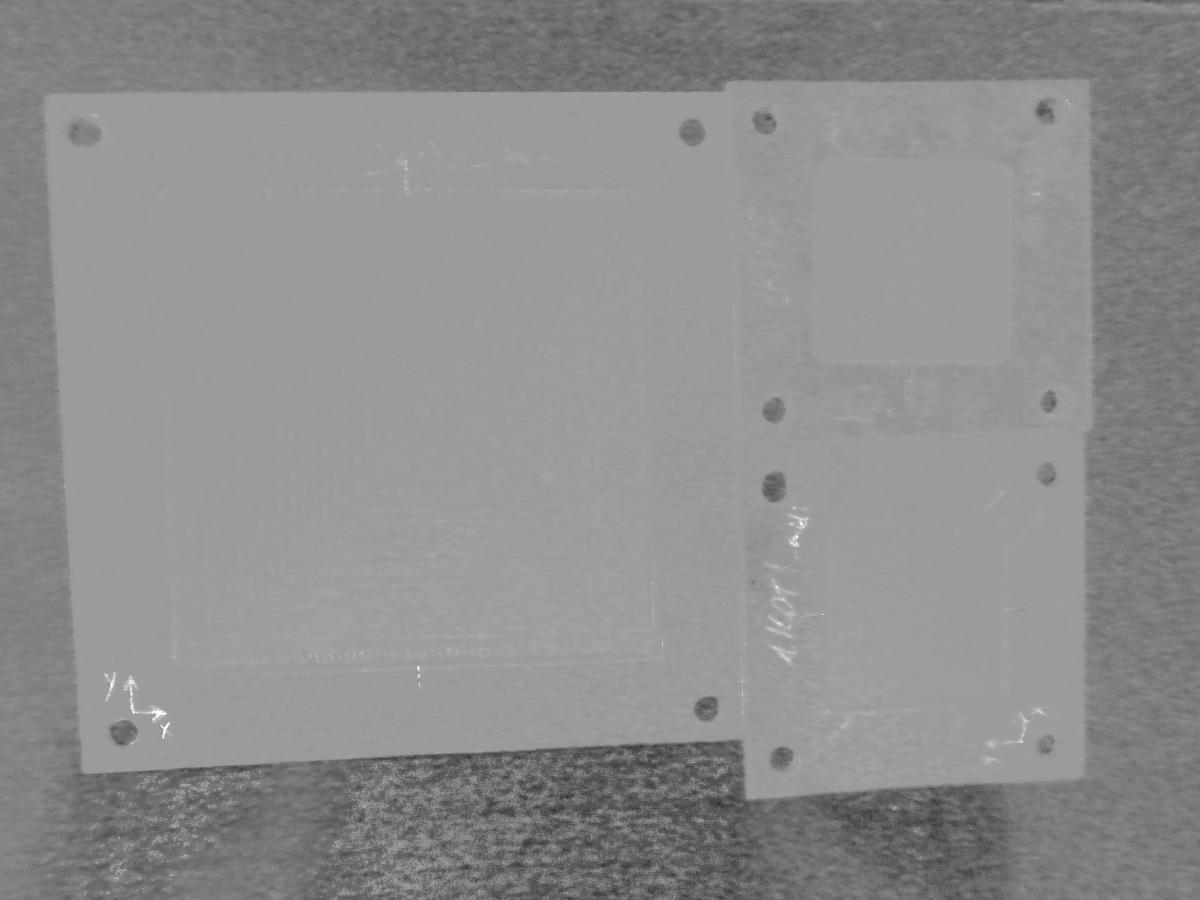

## References

- Krajník, T., Blažiček, J., & Santos, J. M. "Visual Road Following Using Intrinsic Images," *IEEE Intelligent Transportation Systems (ITSC)*, pp. 1640-1646, 2015.